# **Example 1: More on State-Space **

**(Modified from Antoulas/Igor Pontes Course)**

## **Load System**

close all
clear all
clc


% load BeamControl.mat
% A = G.A;
% B = G.B;
% C = G.C;
% D = G.D;

% load beam.mat (378)
load build.mat %(48)

% Check size of system
n = size(A)

n =     48    48


m = size(B)

m =     48     1


p = size(C)

p =      1    48


## **Check Stability**

S = eig(full(A));

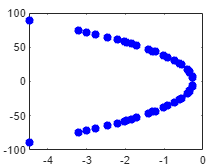

plot(S, 'b*', 'LineWidth',2)

## Let's simulate the system

% Input function --> general
u = @(t) exp(-t).*sin(t);

% Simulation time interval 
tspan = [0, 50];

% Define state-sapce equation --> to be callend by ODE solver
f = @(t,x) A*x + B*u(t);

% I.C.
x0 = zeros(size(A,1), 1);

% Call ODE Solver --> in this case ODE45 (RK45)
opts = odeset('RelTol', 1e-8, 'AbsTol',1e-8);
tic
[t, x]  = ode45(f, tspan, x0, opts);
timeelapse = toc

timeelapse = 0.1240

## Plot Solution --> state variables

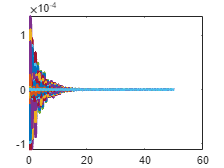

figure;
plot(t, x, 'LineWidth',2)

## Plot Output

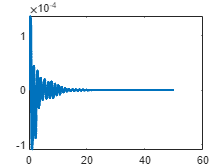

D = 0;
y = C*x';
figure;
plot(t, y,'LineWidth',2)

## **Model Reduction**

sys = ss(full(A), B, C, D);

% MOR by balanced truncation --> using built in functions
[sys_bal,HSV] = balreal(sys);  % Compute balanced realization
elim = (HSV<1e-5);         % Small entries of HSV are negligible states
sys_red = modred(sys_bal,elim); % Remove negligible states

% Using balred --> more accurate for large scale systems
[sys_red_1,INFO] = balred(sys,20)

sys_red_1 =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11        x12        x13        x14        x15        x16        x17        x18        x19        x20
   x1     -0.5689     0.6754    -0.2777    -0.6481      1.369      1.315     -1.766      0.951      1.522     -1.213      1.054     -1.338     -1.283    -0.1383     0.4196     -1.036     0.1436     0.8873     0.1823     0.2053
   x2      -3.123     0.4824      1.022          2     -1.635     -1.687     0.3229     -1.578     -1.377     0.3822    -0.2124    -0.7241     -1.244     0.4328    -0.2209    -0.4541    -0.2083     0.5921    -0.1591     0.1362
   x3      -3.319       3.44     -2.821     -2.015      1.044     0.1744     -2.681     0.8171      2.159     -1.386     0.6528     -3.682     -1.801      1.545    -0.4135     0.3878     -1.453      0.915    -0.2016    -0.4301
   x4     -0.6009   -0.02016     0.1517    -0.3021     0.4134     0.379

INFO =                HSV: [48×1 double]
        ErrorBound: [48×1 double]
    Regularization: 0
                Rr: [48×48 double]
                Ro: [48×48 double]


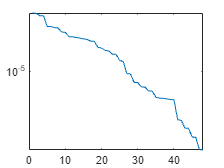


% Plot HSV
semilogy(HSV)


% define simulation for reduced order model
fr = @(t,x) sys_red.A*x + sys_red.B*u(t);

% I.C.
xr0 = zeros(size(sys_red.A,1), 1);

% Call ODE Solver --> in this case ODE45 (RK45)
opts = odeset('RelTol', 1e-8, 'AbsTol',1e-8);
tic
[tr, xr]  = ode45(fr, tspan, xr0, opts);
timeelapser = toc

timeelapser = 0.2245

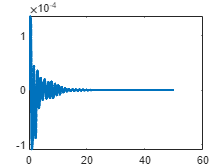

yr = sys_red.C*xr';
figure;
plot(tr, yr,'LineWidth',2)

## **Check Controllability/Observability**

% Controllability Matrix
C_AB = ctrb(A, B);
rankC = rank(C_AB)

rankC = 5


% Obeservabiliyt Matrix
O_AC = obsv(A, C);
rankO = rank(O_AC)

rankO = 5


% Minimal realization --> algorithm only works well for samll systems...
sysmin = minreal(sys)

sysmin =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48
   x1            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           1           0           0           0           0           0           0           0         

## **Check Gramians**

% Controllability Gramian
% Lyapunov Equation --> A*P + P*A' + B*B' = 0
P = lyap(A, B*B');
rankP = rank(P);
% H2norm^2 = trace(C*P*C')
H2normP = sqrt(trace(C*P*C'));

% Observability  Gramian
% Lyapunov Equation --> A'*Q + Q*A + C'*C' = 0
Q = lyap(A, C'*C);
rankQ = rank(Q);
% H2norm^2 = trace(B'*Q*B)
H2normQ = sqrt(trace(B'*Q*B));

% Or can use Matlab built in function directly
% H2 norm
sys_norm2 = norm(sys, 2);
% Hinf norm
sys_norm_inf = norm(sys, 'inf');

# **Example 2:  Recall the Heat Equation into State-Space**


$$\dot{X}(t) = AX(t) + Bu(t)\\
y(t) = CX(t) + Du(t)$$


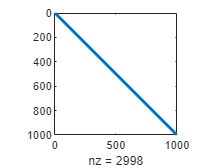

% Number of states
n = 1000;
K = 1;

e = ones(n,1);
AH = spdiags([e -2*e e],-1:1,n,n);
AH(1,1) = -1;

spy(AH)

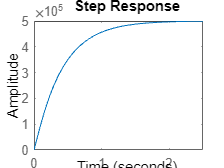

full(AH);

BH =zeros(n,1);
BH(1) = K*n;

% Output  = average temp
CH = (1/n)*ones(1,n);

DH = 0;

%sys = sparss(A, B, C,D);

sysH = ss(full(AH), BH, CH,DH);
step(sysH)

**Another example --> if measuing temperature everywhere**

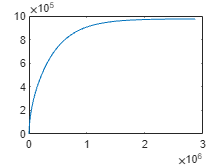

% If output is temp everywhere
CH1 = eye(n);
DH1 = zeros(n,1);

sysH1 = ss(full(AH), BH, CH1, DH1);

[Y, T] =  step(sysH1);
figure;
plot(T, Y(:,25))

# Model Reduction approximation

**Assume one can get the reduced order matrices using some algorithm. In this case,, one can show that using Balanced Trunation method (to be seen in a few lectures), we can approximate the system with the following matrices**

[sysH_bal,g] = balreal(sysH);  % Compute balanced realization
elim = (g<1e-5);         % Small entries of g are negligible states
sysH_red = modred(sysH_bal,elim); % Remove negligible states


$$\dot{X_r}(t) = A_rX_r(t) + B_ru(t)\\
y_r(t) = C_rX_r(t) + D_ru(t)$$


% Define reduced-orer model
% Derived somewhere else
A_r = 1e-6*[-2.256 1.775 -0.6057; -1.775 -16.63 12.21; -0.6057 -12.21 -40.66];
B_r = [-1.074; -0.4136; -0.1442];
C_r = [-1.074 0.4136 -0.1442];
D_r = D;

One can now form the reduced state-space system

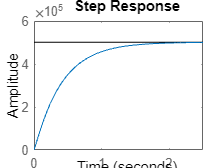

sys_r = ss(A_r, B_r, C_r, D_r);
figure;
step(sys_r)

Comparisons

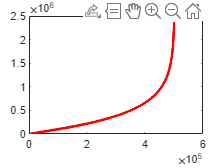

[Tr, Yr] = step(sys_r);
[T, Y] = step(sys);
figure;
plot(T, Y, Tr, Yr, 'r', LineWidth=2)